# CIV102 BRIDGE DESIGN PROJECT: DESIGN CALCULATIONS: Final Design Cross Section 2: Load Case 2 

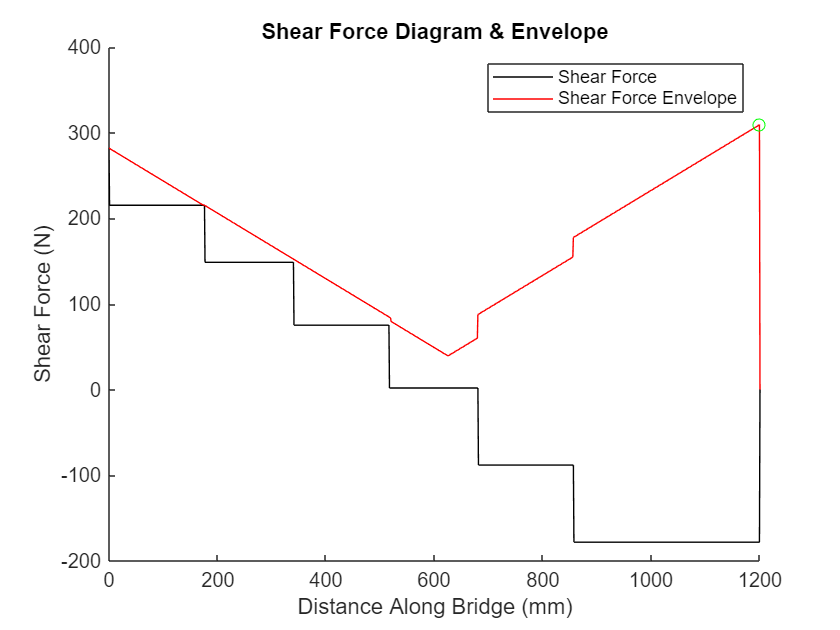

% GROUP MEMBERS: ALIZA AZAM, CHARLOTTE WINTER AND BELINDA ZHANG

% THIS SCRIPT CONTAINS CODE FOR OUR FINAL DESIGNS CROSS SECTION 2 UNDER LOAD CASE 2

clear; close all;

%% Initialize Parameters
bridge_length = 1200;   % Length of the bridge
n = 1200;   % Discretize into 1 mm segments
P = 400;    % Total weight of the train [N]
x = linspace(0, bridge_length, n+1); % x-axis    

%% SFD, BMD Under Train Loading
x_train = [52, 228, 392, 568, 732, 908]; % train load locations
P_train = [1 1 1.1 1.1 1.35 1.35] * (P/6);

n_train = 345;    % number of train start locations
SFDi = zeros(n_train, n+1);     % 1 SFD for each train location
BMDi = zeros(n_train, n+1);     % 1 BMD for each train location

for i = 1:n_train
    x_start_loc = i - 52;  % Starting location of the train
    x_train_mov = max(1, min(round(x_train + x_start_loc), n));

    % Step 1: Sum of moments at point A
    A_y = (sum(P_train .* x_train_mov)) / bridge_length; % Reaction force at 'y' solved 

    % Step 2: Sum of Fy equation, rearranged to solve for at point B, B_y
    B_y = sum(P_train) - A_y;
    initial_v = B_y; % initial shear force at left support (point B)

    % Step 3-5: Calculate shear force across segments
    SFDi(i, 1:x_train_mov(1)) = initial_v;
    for k = 1:length(P_train)
        initial_v = initial_v - P_train(k);
        
        if k < length(P_train)
            SFDi(i, x_train_mov(k):x_train_mov(k+1)) = initial_v;
        end
    end
    SFDi(i, x_train_mov(end):n) = initial_v;
    
    % Step 6: Update Point A (right supports) shear force value  
    initial_v = initial_v + A_y;
    SFDi(i, n+1) = initial_v;
    
    % Step 7: Integrate SFD to obtain BMD
    BMDi(i,:) = cumtrapz(SFDi(i,:));
end

SFD = max(abs(SFDi));   % the absolute maximum values of shear force at all locations
BMD = max(BMDi);        % the maximum value of all bending moments at all locations

% Plot SFD and BMD
figure(1)
hold on
plot(x, SFDi(2,:), "k")
plot(x, SFD, "r")   % SFD for maximum shear force
title("Shear Force Diagram & Envelope")
xlabel('Distance Along Bridge (mm)')
ylabel('Shear Force (N)')
[~, max_shear_idx] = max(SFD);  % find index of max moment
plot(x(max_shear_idx), SFD(max_shear_idx), "go") % plot max moment
legend("Shear Force", "Shear Force Envelope")
hold off

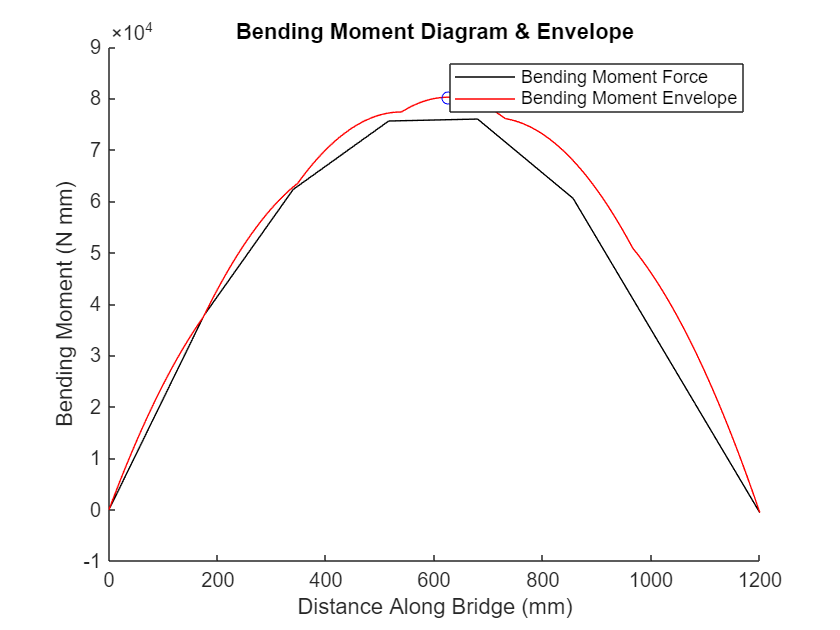


figure(2)
hold on
plot(x, BMDi(1,:), "k")
plot(x, BMD, "r")   % BMD for maximum bending moment
title("Bending Moment Diagram & Envelope")
xlabel('Distance Along Bridge (mm)')
ylabel('Bending Moment (N mm)')
[~, max_moment_idx] = max(BMD);  % find index of max moment
plot(x(max_moment_idx), BMD(max_moment_idx), "bo") % plot max moment
legend("Bending Moment Force", "Bending Moment Envelope")
hold off


%% Calculate Sectional Properties
% Step 1: Find centroidal axis of i number of rectangles
b = [120, 1.27, 1.27, 10, 10, 0]; % base of rectangle
height = [3.81, 90, 90, 1.27, 1.27, 0]; % height of rectangle
A_glue = b.*height; % Calculate area of each rectangle and store in array

% Step 2: Calculate for y bar
yi = [101.905, 50, 50, 99.365, 99.365, 0];
sum_yi_and_area = sum(A_glue.*yi);
ybar = sum_yi_and_area/sum(A_glue)

ybar = 85.1305


% Step 3: Calculate for y bottom and y top
h_tot = 103.81; % Inputted Value
ybot = ybar

ybot = 85.1305

y_top = h_tot - ybar

y_top = 18.6795


% Step 4: Calculate I (2nd Moment of Area)
I_nought = sum((b.*(height.^3))/12);
d = abs(ybar - yi);
I_parallel = sum(A_glue.*(d.^2));

I = I_nought + I_parallel

I = 5.7078e+05


% Step 5: Calculate Q at centroidal axes
d_i = [41.95955]; % Inputted Values (dist. from centroidal axes to centroid of each area (above or below))
A_i = [(1.27*83.9191)]; % Inputted Values (area of rectangles above or below centroidal axis)

Q_cent = sum(A_i.*d_i)

Q_cent = 4.4719e+03


% Step 6: Q at glue location
d_glue = 15.2859; % Inputted Value (dist. from centroid of area of interest to y bar)
A_glue = 457.2; % The area or areas that would detach if the glue fails

Q_glue = A_glue*d_glue

Q_glue = 6.9887e+03


%% Calculate Applied Stress
V = SFD;
t_cent = 2*1.27; % Inputted Value (thickness @ axes of interest)
a_glue = 22.54; % Inputted Value (area where glue is used)

BMD_maxValue = max(BMD)

BMD_maxValue = 8.0231e+04

SFD_maxValue = max(SFD)

SFD_maxValue = 309.4639

S_top = (BMD_maxValue*y_top)/I

S_top = 2.6256

S_bot = (BMD_maxValue*ybot)/I

S_bot = 11.9662

T_cent = (SFD_maxValue.*Q_cent)./(I*t_cent)

T_cent = 0.9546

T_glue = (SFD_maxValue.*Q_glue)./(I*a_glue)

T_glue = 0.1681


% Material and Thin Plate Buckling Capacities
E = 4000;
thickness = 1.27;
poissons_ratio = 0.2;

% Given Material Properties 
S_tens = ones(1201, 1).*30; 
S_comp = ones(1201, 1).*6;
T_max = ones(1201, 1).*4;
T_gluemax = ones(1201, 1).*2; 

% Scenario #1 of Plate Buckling
k = 4; 
t = 3.81;
b = 103.81; % Inputted Value (height)
S_buck1= ((k*pi^2*E)/12*(1-(poissons_ratio^2)))*((t/b)^2)

S_buck1 = 17.0169


% Scenario #2 of Plate Buckling (one edge is restrained from moving while the other edge is free to move)
k = 0.425;
b = 20; % Inputted Value (height)
S_buck2 = ((k*pi^2*E) / (12*(1 - (poissons_ratio^2))))*(thickness/b)^2

S_buck2 = 5.8728


% Scenario #3 of Plate Buckling
k = 6;
b = 16.0809; % Inputted Value (height)
S_buck3 = ((k*pi^2*E) / (12*(1 - (poissons_ratio^2))))*(thickness/b)^2

S_buck3 = 128.2464


% Scenario #4 of Plate Buckling
k = 5;
height = 101.27;
a = 245; % spacing of diaphragms
T_crit = ((5*pi^2*E)/(12*(1 - (poissons_ratio^2))))*(((thickness/height)^2) + ((thickness/a)^2))

T_crit = 3.1552

 
%% FOS
FOS_tens = min(S_tens'./ S_bot)

FOS_tens = 2.5071

FOS_comp = min(S_comp'./ S_top)

FOS_comp = 2.2852

FOS_shear = min(T_max'./T_cent)

FOS_shear = 4.1904

FOS_glue = min(T_gluemax'./T_glue)

FOS_glue = 11.8973

FOS_buck1 = min(S_buck1'./ S_top)

FOS_buck1 = 6.4811

FOS_buck2 = min(S_buck2'./ S_top)

FOS_buck2 = 2.2367

FOS_buck3 = min(S_buck3'./ S_top)

FOS_buck3 = 48.8440

FOS_buckV = min(T_crit'./ T_cent)

FOS_buckV = 3.3054


FOS = [FOS_tens, FOS_comp, FOS_shear, FOS_glue, FOS_buck1, FOS_buck2, FOS_buck3, FOS_buckV]

FOS =     2.5071    2.2852    4.1904   11.8973    6.4811    2.2367   48.8440    3.3054



%% Min FOS & the Failure Load P Fail
minFOS = min(FOS) % Min of all FOS values

minFOS = 2.2367

P_f = minFOS * P;
disp(P_f + " N")

894.6833 N



% Vfail and Mfail
Mf_tens = FOS_tens.*BMD;
Mf_comp = FOS_comp.*BMD;
Mf_buck1 = FOS_buck1.*BMD;
Mf_buck2 = FOS_buck2.*BMD;
Mf_buck3 = FOS_buck3.*BMD;
Vf_shear = FOS_shear.*SFD;
Vf_glue = FOS_glue.*SFD;
Vf_buckV = FOS_buckV.*SFD;

disp(max(Mf_tens))

   2.0114e+05



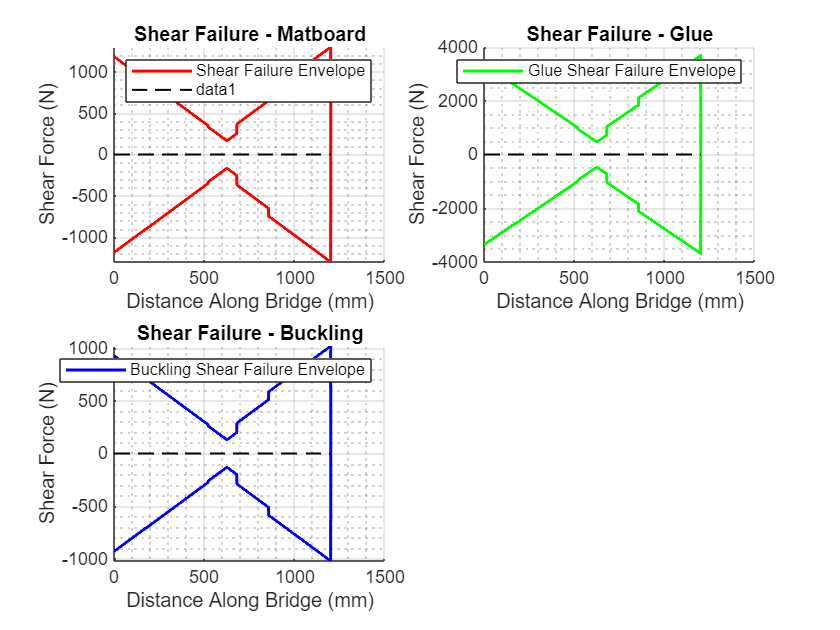

% Output plots of Vfail and Mfail
% Plot of Vfail
figure;
subplot(2, 2, 1);
hold on; grid on; grid minor;
plot(x, Vf_shear, 'r', 'LineWidth', 1.5);
plot(x, -Vf_shear, 'r', 'LineWidth', 1.5);
title('Shear Failure - Matboard');
xlabel('Distance Along Bridge (mm)');
ylabel('Shear Force (N)');
legend("Shear Failure Envelope")
plot([0, bridge_length], [0, 0], 'k--', 'LineWidth', 1);
hold off;

subplot(2, 2, 2);
hold on; grid on; grid minor;
plot(x, Vf_glue, 'g', 'LineWidth', 1.5);
plot(x, -Vf_glue, 'g', 'LineWidth', 1.5);
title('Shear Failure - Glue');
xlabel('Distance Along Bridge (mm)');
ylabel('Shear Force (N)');
legend("Glue Shear Failure Envelope")
plot([0, bridge_length], [0, 0], 'k--', 'LineWidth', 1);
hold off;
legend("Glue Shear Failure Envelope")

subplot(2, 2, 3);
hold on; grid on; grid minor;
plot(x, Vf_buckV, 'b', 'LineWidth', 1.5);
plot(x, -Vf_buckV, 'b', 'LineWidth', 1.5);
title('Shear Failure - Buckling');
xlabel('Distance Along Bridge (mm)');
ylabel('Shear Force (N)');
legend('Buckling Shear Failure Envelope')
plot([0, bridge_length], [0, 0], 'k--', 'LineWidth', 1);
hold off;

subplot(2,2,3)
legend("Buckling Shear Failure Envelope")

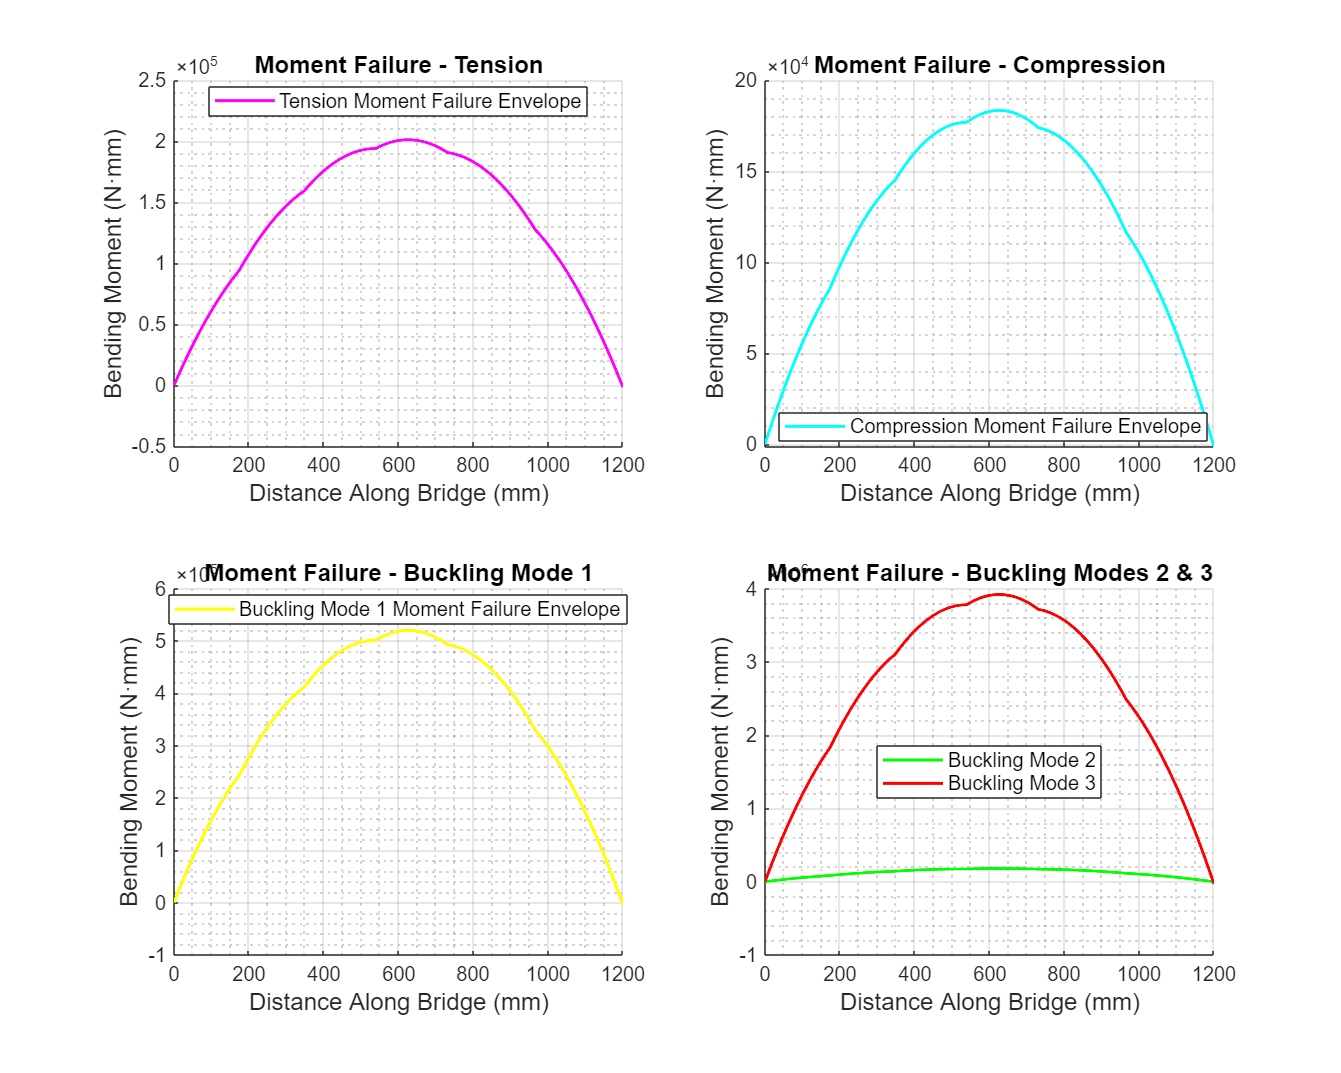

% Plot of Mfail
figure;

% Subplot 1: Tension
subplot(2, 2, 1);
hold on; grid on; grid minor;
plot(x, Mf_tens, 'm', 'LineWidth', 1.5);
title('Moment Failure - Tension', 'FontSize', 12, 'Interpreter', 'none');
xlabel('Distance Along Bridge (mm)', 'FontSize', 12);
ylabel('Bending Moment (N·mm)', 'FontSize', 12);
legend('Tension Moment Failure Envelope', 'FontSize', 10, 'Location', 'best');
hold off;

% Subplot 2: Compression
subplot(2, 2, 2);
hold on; grid on; grid minor;
plot(x, Mf_comp, 'c', 'LineWidth', 1.5);
title('Moment Failure - Compression', 'FontSize', 12, 'Interpreter', 'none');
xlabel('Distance Along Bridge (mm)', 'FontSize', 12);
ylabel('Bending Moment (N·mm)', 'FontSize', 12);
legend('Compression Moment Failure Envelope', 'FontSize', 10, 'Location', 'best');
hold off;

% Subplot 3: Buckling Mode 1
subplot(2, 2, 3);
hold on; grid on; grid minor;
plot(x, Mf_buck1, 'y', 'LineWidth', 1.5);
title('Moment Failure - Buckling Mode 1', 'FontSize', 12, 'Interpreter', 'none');
xlabel('Distance Along Bridge (mm)', 'FontSize', 12);
ylabel('Bending Moment (N·mm)', 'FontSize', 12);
legend('Buckling Mode 1 Moment Failure Envelope', 'FontSize', 10, 'Location', 'best');
hold off;

% Subplot 4: Buckling Modes 2 & 3
subplot(2, 2, 4);
hold on; grid on; grid minor;
plot(x, Mf_buck2, 'g', 'LineWidth', 1.5);
plot(x, Mf_buck3, 'r', 'LineWidth', 1.5);
title('Moment Failure - Buckling Modes 2 & 3', 'FontSize', 12, 'Interpreter', 'none');
xlabel('Distance Along Bridge (mm)', 'FontSize', 12);
ylabel('Bending Moment (N·mm)', 'FontSize', 12);
legend('Buckling Mode 2', 'Buckling Mode 3', 'FontSize', 10, 'Location', 'best');
hold off;

% Adjust figure size and overall layout
set(gcf, 'Position', [100, 100, 1000, 800]); % Resize the figure for better spacing